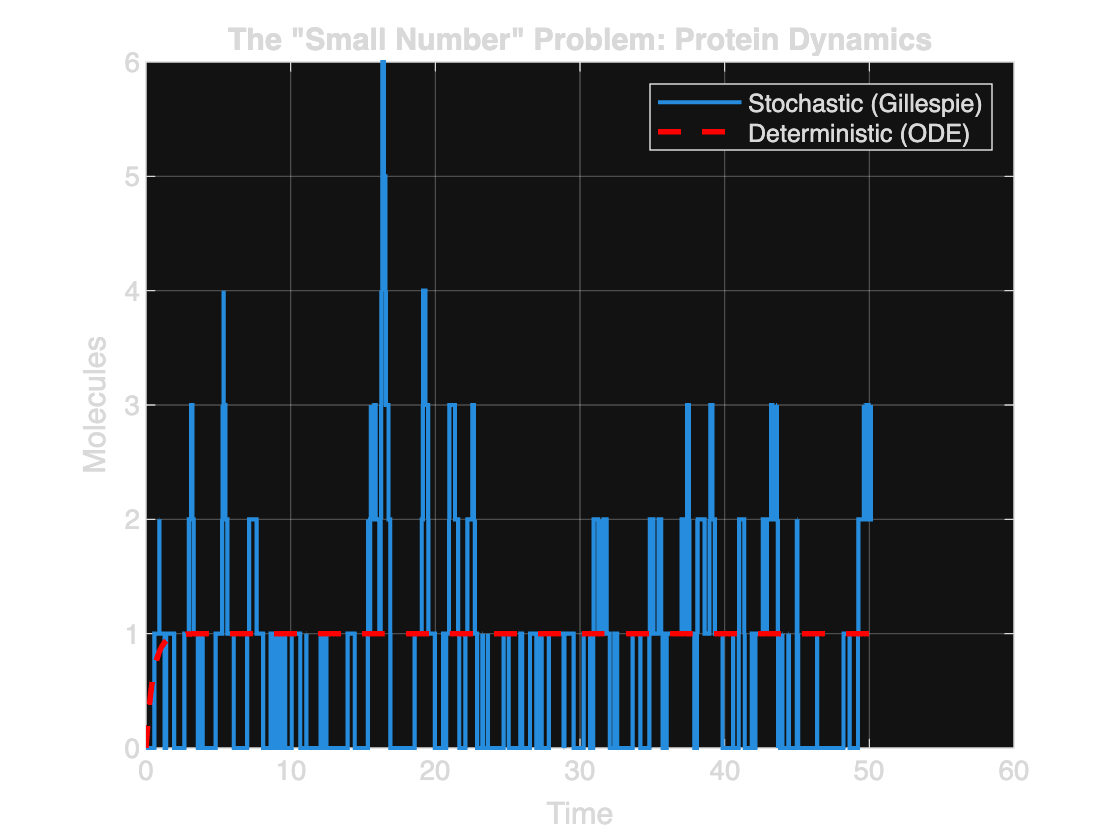

%% Section 1: Deterministic vs. Stochastic (Birth-Death Process)
% System: Source -> Protein (k1), Protein -> Null (k2)
k1 = 2;   % Production rate
k2 = 2; % Degradation rate
T_end = 50;
X0 = 0;   % Initial protein count

% 1. Deterministic Solution (ODE: dX/dt = k1 - k2*X)
t_ode = 0:0.1:T_end;
X_ode = (k1/k2) * (1 - exp(-k2 * t_ode));

% 2. Stochastic Simulation (Simple Gillespie)
t = 0; X = X0;
t_hist = t; X_hist = X;

while t < T_end
    a1 = k1;          % Propensity of production
    a2 = k2 * X;      % Propensity of degradation
    a0 = a1 + a2;
   
    dt = -log(rand)/a0; % Time to next event
    t = t + dt;
   
    if rand < a1/a0
        X = X + 1;
    else
        X = X - 1;
    end
    t_hist(end+1) = t; X_hist(end+1) = X;
end

% Visualization
figure('Color', 'w');
stairs(t_hist, X_hist, 'LineWidth', 1.5, 'DisplayName', 'Stochastic (Gillespie)');
hold on;
plot(t_ode, X_ode, 'r--', 'LineWidth', 2, 'DisplayName', 'Deterministic (ODE)');
xlabel('Time'); ylabel('Molecules');
title('The "Small Number" Problem: Protein Dynamics');
legend; grid on;

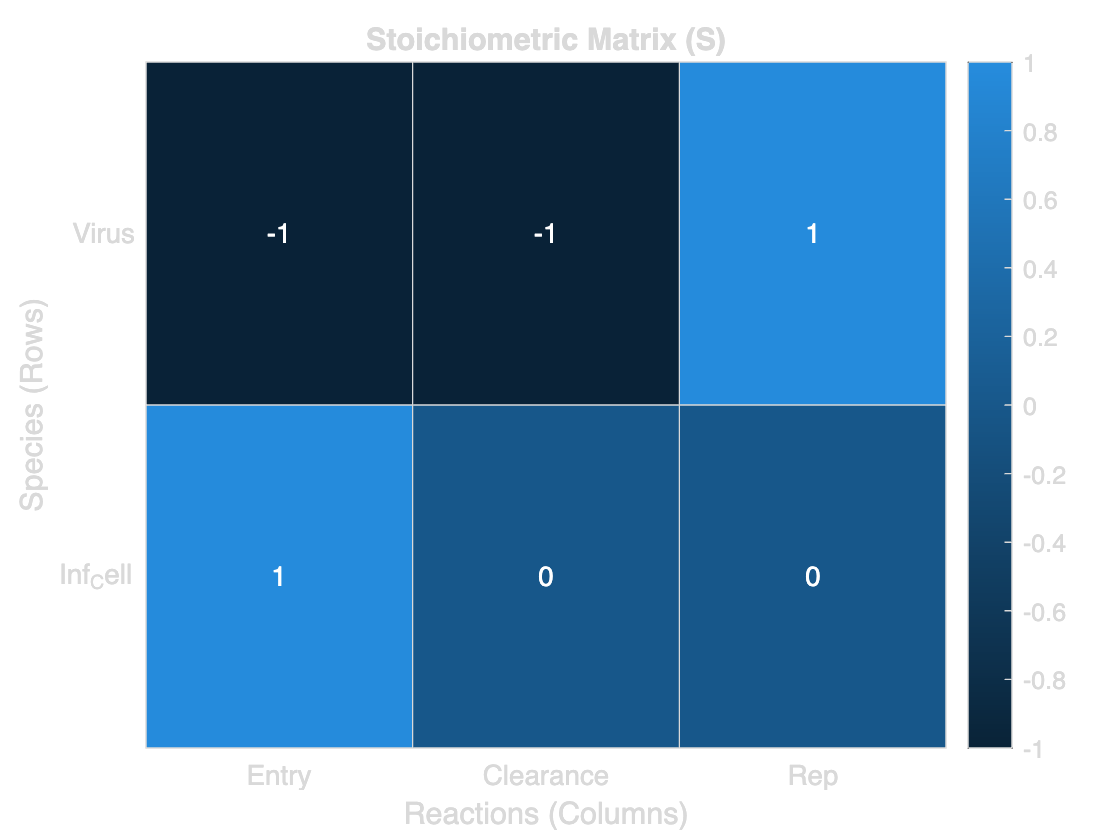

%% 2a: Define System Architecture (The Map)
% Species: [V (Virus); I (Infected Cell)]
% Reactions: 1. Entry (V -> I), 2. Clearance (V -> 0), 3. Replication (I -> I + V)

S = [-1, -1,  1;   % Change in Virus
      1,  0,  0];  % Change in Infected Cells

% Visualization: Heatmap of the Stoichiometric Matrix
figure('Color', 'w');
h = heatmap({'Entry','Clearance','Rep'}, {'Virus','Inf_Cell'}, S);
title('Stoichiometric Matrix (S)');
ylabel('Species (Rows)'); xlabel('Reactions (Columns)');

%% 2a: Define System Architecture (The Map)
% Species: [V (Virus); I (Infected Cell)]
% Reactions: 1. Entry (V -> I), 2. Clearance (V -> 0), 3. Replication (I -> I + V)

S = [-1, -1,  1;   % Change in Virus (Row 1)
      1,  0,  0];  % Change in Infected Cells (Row 2)

% Visualization: Heatmap
% Note: We do NOT use legend here. The row/col labels are sufficient.
figure('Color', 'w');
h = heatmap({'Entry','Clearance','Rep'}, {'Virus','Inf_Cell'}, S);
h.Title = 'Stoichiometric Matrix (S)';
h.YLabel = 'Species (Rows)';
h.XLabel = 'Reactions (Columns)';

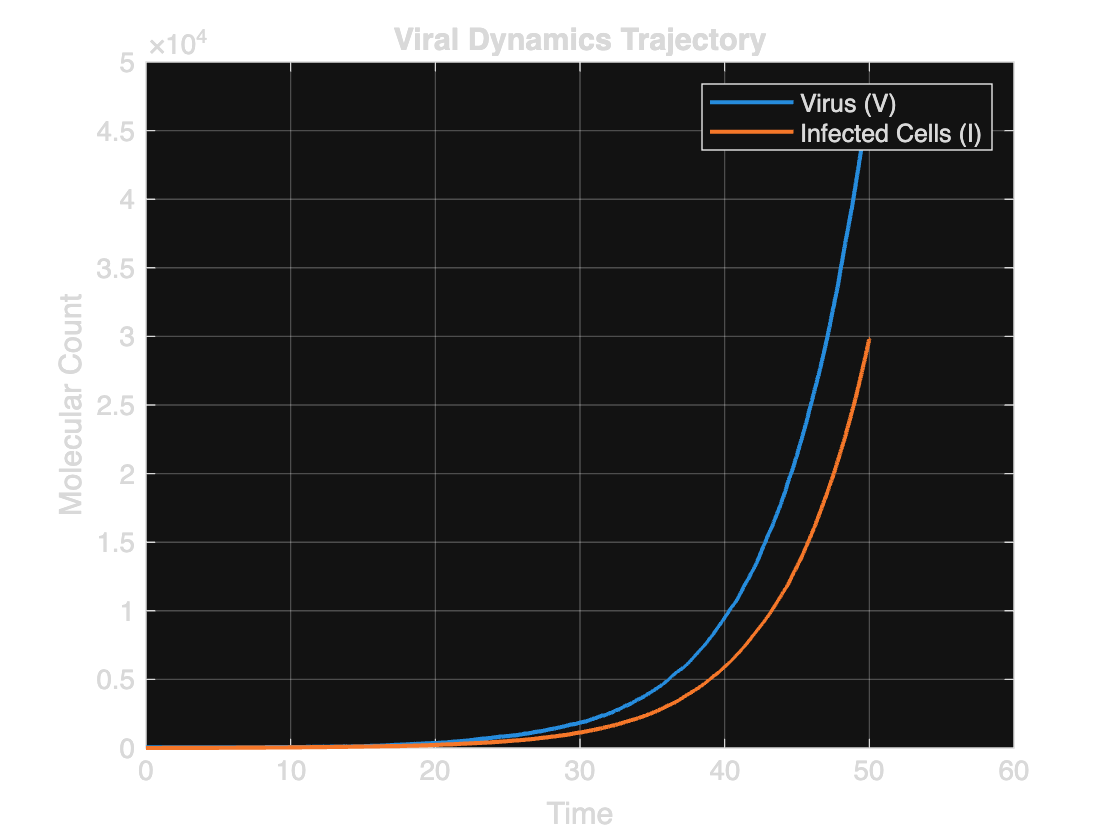


%% 2b: Run the Simulation
x0 = [50; 0];
t_span = [0 50];

% Rates: k_entry, k_clearance, k_replication
k = [0.1, 0.05, 0.5];
prop_func = @(x) [k(1)*x(1); k(2)*x(1); k(3)*x(2)];

% Run the engine
[t, x] = gillespie_direct(S, prop_func, x0, t_span);

% Plot the results
% Note: stairs DOES support legend because it has multiple lines.
figure('Color', 'w');
stairs(t, x, 'LineWidth', 1.5);
xlabel('Time');
ylabel('Molecular Count');
title('Viral Dynamics Trajectory');

% This legend works here because it corresponds to the two lines in x
legend({'Virus (V)', 'Infected Cells (I)'}, 'Location', 'northeast');
grid on;

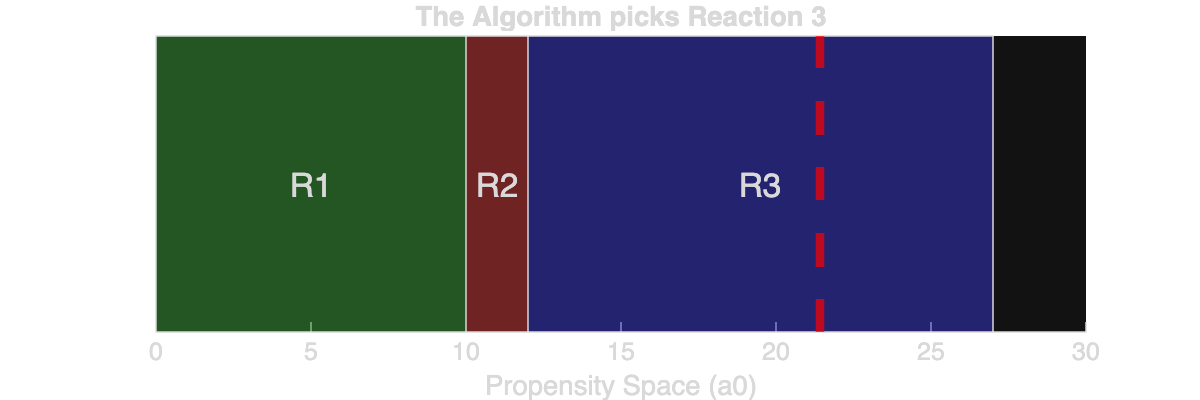

%% 2c: Visualizing Selection (The "Roulette Wheel")
% Let's visualize a single "decision" the algorithm makes
current_props = [10, 2, 15]; % Example: High replication, low clearance
a0 = sum(current_props);
cum_a = [0, cumsum(current_props)];

figure('Color', 'w', 'Position', [100 100 600 200]); hold on;
colors = [0.2 0.6 0.2; 0.8 0.2 0.2; 0.2 0.2 0.8]; % Green, Red, Blue
for i = 1:3
    rectangle('Position', [cum_a(i), 0, current_props(i), 1], 'FaceColor', colors(i,:), 'FaceAlpha', 0.5);
    text(cum_a(i) + current_props(i)/2, 0.5, ['R', num2str(i)], 'FontSize', 12, 'HorizontalAlignment', 'center');
end
r2 = rand * a0;
xline(r2, 'r--', 'LineWidth', 3);
title(['The Algorithm picks Reaction ', num2str(find(cumsum(current_props)>=r2,1))]);
xlabel('Propensity Space (a0)'); set(gca, 'YTick', []);

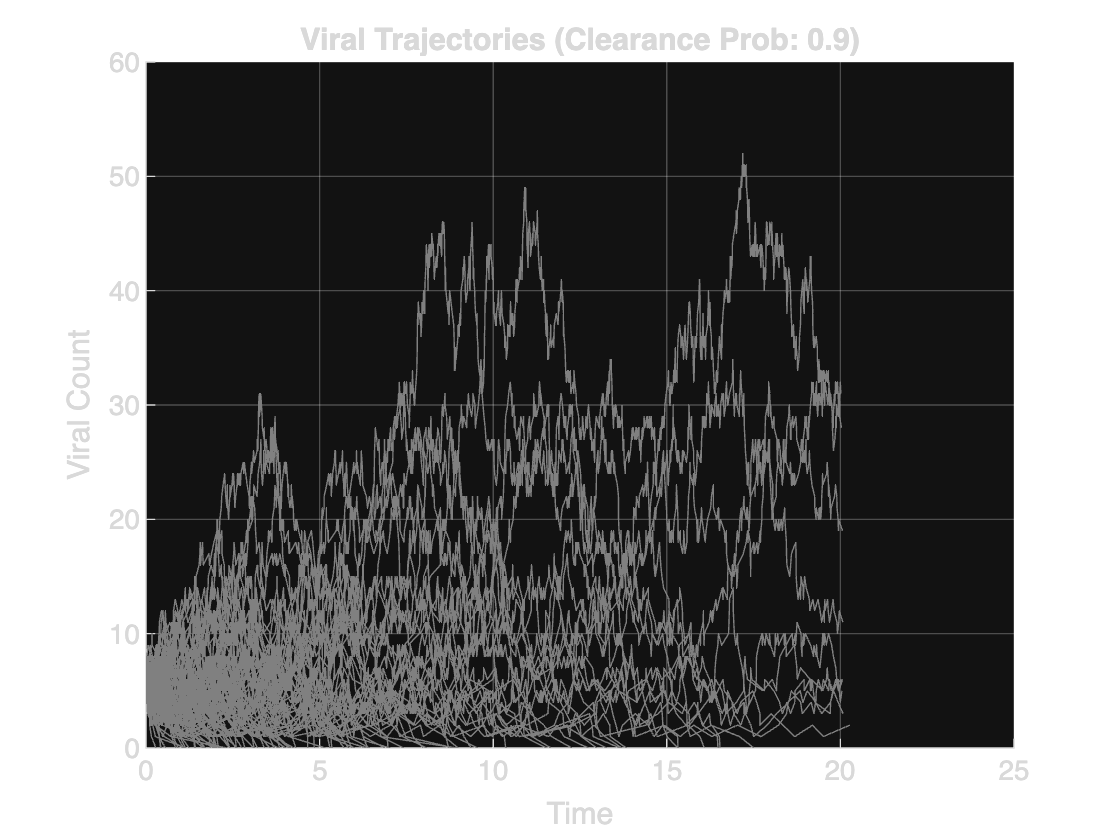

%% Section 3: Medical Application - Stochastic Viral Infection
% System:
% R1: V -> 2V (Replication, rate k_rep)
% R2: V -> 0  (Immune Clearance, rate k_clear)

k_rep = 1.0;
k_clear = 1.1; % Clearance is slightly higher than replication
V0 = 5;        % Start with 5 virions
T_max = 20;
num_sims = 100;

figure('Color', 'w'); hold on;
extinct_count = 0;

for i = 1:num_sims
    % Define Stoichiometry: [Change in V]
    S = [1, -1];
    % Define Propensities: [k_rep*V, k_clear*V]
    p_func = @(x) [k_rep*x(1); k_clear*x(1)];
   
    [t, v] = gillespie_direct(S, p_func, V0, [0 T_max]);
   
    % Plot individual trajectories
    p = plot(t, v, 'Color', [0.5 0.5 0.5 0.2]);
    if v(end) == 0, extinct_count = extinct_count + 1; end
end

title(['Viral Trajectories (Clearance Prob: ', num2str(extinct_count/num_sims), ')']);
xlabel('Time'); ylabel('Viral Count');
grid on;

%% --- EVERYTHING ABOVE THIS LINE IS THE MAIN SCRIPT ---
% (No code or variables can be defined after the function block below)

function [t_out, x_out] = gillespie_direct(S, prop_func, x0, t_span)
    % Initialize variables
    t = t_span(1);
    x = x0(:);       % Ensure x is a column vector
    t_out = t;
    x_out = x';      % Store states as rows
   
    % Main Gillespie Loop
    while t < t_span(2)
        % 1. Calculate propensities based on current state
        a = prop_func(x);
        a0 = sum(a);      % Total propensity
       
        % If no more reactions can happen, exit
        if a0 <= 0, break; end
       
        % 2. Draw Time Step (tau) - Exponentially distributed
        % Slide 51: The time to the next reaction
        tau = -log(rand) / a0;
       
        % 3. Draw Reaction (reac_idx) - Proportional selection
        % Slide 51: Which reaction occurs?
        r2 = rand * a0;
        reac_idx = find(cumsum(a) >= r2, 1);
       
        % 4. Update the system
        t = t + tau;
        x = x + S(:, reac_idx); % Apply the stoichiometric change
       
        % 5. Record the data
        t_out(end+1) = t;
        x_out(end+1, :) = x';
    end
end
